clc; clear; close all;

% Put this at the very top of your script, before any figure/gca calls:

set(groot, ...
    'defaultAxesFontName',     'Helvetica', ...   % axes tick labels & titles
    'defaultTextFontName',     'Helvetica', ...   % any text()
    'defaultLegendFontName',   'Helvetica', ...   % legend text
    'defaultColorbarFontName', 'Helvetica' ...    % colorbar labels
);

%% -----------|| USER INPUT ||-----------
addpath('C:\Users\allis\OneDrive - Yale University\Imspector\Excel');
outputFolder = 'C:\Users\allis\OneDrive - Yale University\Figures';

fileName = 'Ex_Figs.xlsx';
data = readtable(fileName); 
data = data(2:end, :); % skip headers

x1 = table2array(data(:,1)); % lateral distance (µm)
x2 = table2array(data(:,2)); % lateral intensity
x3 = table2array(data(:,3)); % axial distance (µm)
x4 = table2array(data(:,4)); % axial intensity

%% -----------|| Crop + Prepare Data ||-----------
xLat = x1(23:73);       % already in µm
yLat = x2(23:73);
xAxial = x3(40:140);    % expanded to capture more tails
yAxial = x4(40:140);

chosenStep = 0.1; % for consistent tick spacing
fprintf('Chosen x-axis increment: %.2f µm\n', chosenStep);

Chosen x-axis increment: 0.10 µm


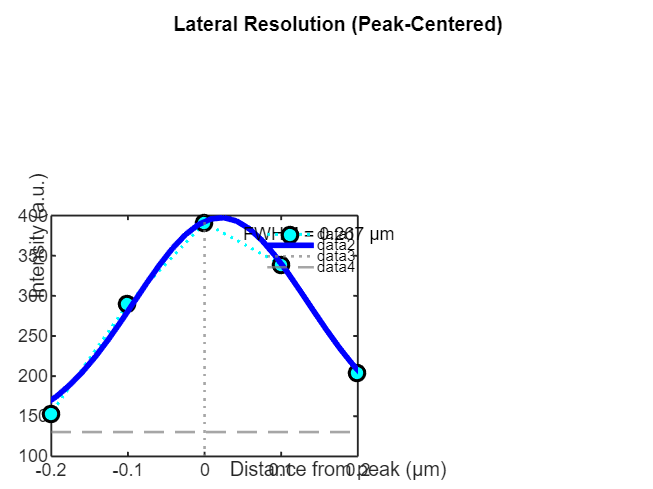

%% -----------|| LATERAL FIT + PLOT ||-----------
f1 = figure('Name','Lateral Resolution Fit'); clf; hold on;
gaussian = @(p, x) p(1) * exp(-((x - p(2)).^2) / (2 * p(3)^2)) + p(4);
errorFxn = @(p) sum((gaussian(p, xLat) - yLat).^2);
[~, maxLatIdx] = max(yLat);
x0_lat = xLat(maxLatIdx);
initGuessLat = [max(yLat), x0_lat, 0.1, min(yLat)];
options = optimset('MaxIter', 500, 'Display', 'off');
optLat = fminsearch(errorFxn, initGuessLat, options);
FWHM_lat = 2.355 * optLat(3);  % FWHM

xLatShifted = xLat - x0_lat;
XfitLatShifted = linspace(min(xLatShifted), max(xLatShifted), 300);
YfitLat = gaussian(optLat, XfitLatShifted + x0_lat);
maxLatPeak = max(max(yLat), max(YfitLat));

plot(xLatShifted, yLat, 'co:', 'MarkerFaceColor', 'c', 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
plot(XfitLatShifted, YfitLat, 'b-', 'LineWidth', 2.2);
xline(0,':', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);
yline(optLat(4), '--', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);
xlabel('Distance from peak (µm)');
ylabel('Intensity (a.u.)');
xlim([-0.2, 0.2]);
set(gca, 'XTick', -0.2:chosenStep:0.2);
set(gca, 'LineWidth', 0.75, 'FontSize', 7);
box on;
title('Lateral Resolution (Peak-Centered)');
legend('Location', 'northeast', 'Box', 'off', 'FontSize', 6);
text(0.05, 0.95 * maxLatPeak, sprintf('FWHM = %.3f µm', FWHM_lat), 'FontSize', 7, 'FontName', 'Helvetica', 'Color', 'k');

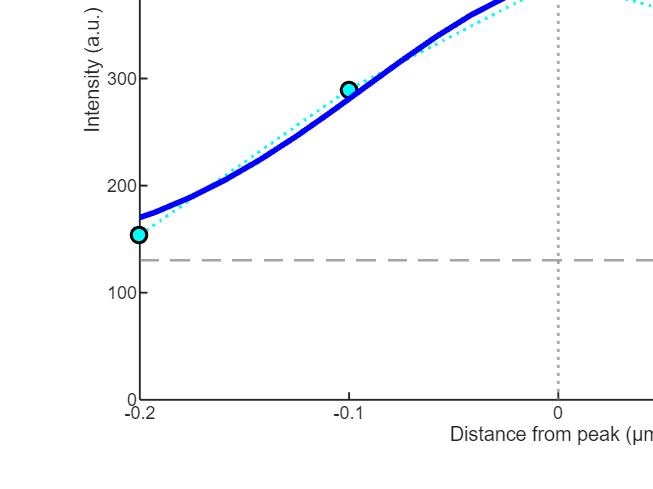

%% -----------|| AXIAL FIT + PLOT ||-----------
f2 = figure('Name','Axial Resolution Fit'); clf; hold on;
errorFxnAx = @(p, x) sum((gaussian(p, x) - yAxial).^2);
[~, maxAxIdx] = max(yAxial);
x0_ax = xAxial(maxAxIdx);
initGuessAx = [max(yAxial), x0_ax, 0.5, min(yAxial)];
optAx = fminsearch(@(p) errorFxnAx(p, xAxial), initGuessAx, options);
FWHM_ax = 2.355 * optAx(3);

xAxialShifted = xAxial - x0_ax;
XfitAxShifted = linspace(min(xAxialShifted), max(xAxialShifted), 300);
YfitAx = gaussian(optAx, XfitAxShifted + x0_ax);
maxAxPeak = max(max(yAxial), max(YfitAx));

plot(xAxialShifted, yAxial, 'co:', 'MarkerFaceColor', 'c', 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
plot(XfitAxShifted, YfitAx, 'b-', 'LineWidth', 2.2);
xline(0,':', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);
yline(optAx(4), '--', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);
xlabel('Distance from peak (µm)');
ylabel('Intensity (a.u.)');
xlim([-1.2, 1.2]);
set(gca, 'XTick', -1.2:chosenStep:1.2);
set(gca, 'LineWidth', 0.75, 'FontSize', 7);
box on;
title('Axial Resolution (Peak-Centered)');
legend('Location', 'northeast', 'Box', 'off', 'FontSize', 6);
text(0.05, 0.95 * maxAxPeak, sprintf('FWHM = %.3f µm', FWHM_ax), 'FontSize', 7, 'FontName', 'Helvetica', 'Color', 'k');

%% -----------|| Set shared y-limits and save ||-----------
finalYLim = max(maxLatPeak, maxAxPeak) + 100;

figure(f1); ylim([0, finalYLim]);
print(f1, fullfile(outputFolder, 'lateral_resolution_fit_peakcentered'), '-dpng', '-r600');

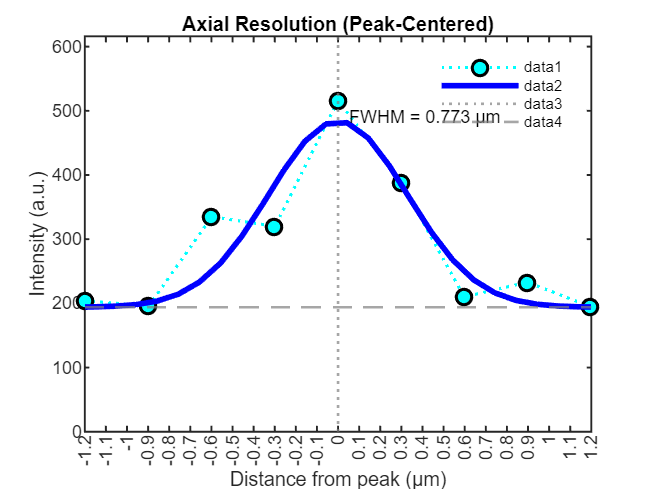


figure(f2); ylim([0, finalYLim]);
print(f2, fullfile(outputFolder, 'axial_resolution_fit_peakcentered'), '-dpng', '-r600');


disp('Both peak-centered plots saved with FWHM annotations.');

Both peak-centered plots saved with FWHM annotations.


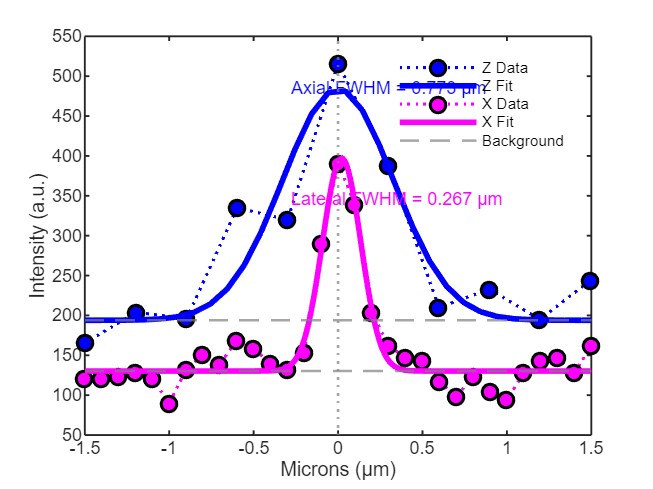

%% -----------|| COMBINED PLOT ||-----------
f3 = figure;
hold on
p1 = plot(xAxialShifted, yAxial, 'bo:', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k', 'LineWidth', 1.2, 'DisplayName', 'Z Data');
p2 = plot(XfitAxShifted, YfitAx, 'b-', 'LineWidth', 2.2, 'DisplayName', 'Z Fit');
yline(optAx(4), '--', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);

p3 = plot(xLatShifted, yLat, 'mo:', 'MarkerFaceColor', 'm', 'MarkerEdgeColor', 'k', 'LineWidth', 1.2, 'DisplayName', 'X Data');
p4 = plot(XfitLatShifted, YfitLat, 'm-', 'LineWidth', 2.2, 'DisplayName', 'X Fit');
p5 = yline(optLat(4), '--', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1, 'DisplayName', 'Background');

xline(0, ':', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);
xlabel('Microns (µm)');
ylabel('Intensity (a.u.)');
xlim([-1.5, 1.5]);
set(gca, 'LineWidth', 0.75, 'FontSize', 7);
box on;
legend([p1, p2, p3, p4, p5], 'Location', 'northeast', 'Box', 'off', 'FontSize', 6);

text(-0.28, 0.94 * maxAxPeak, sprintf('Axial FWHM = %.3f µm', FWHM_ax), ...
    'FontSize', 7, 'FontName', 'Helvetica', 'Color', 'b');

text(-0.28, 0.87 * maxLatPeak, sprintf('Lateral FWHM = %.3f µm', FWHM_lat), ...
    'FontSize', 7, 'FontName', 'Helvetica', 'Color', 'm');

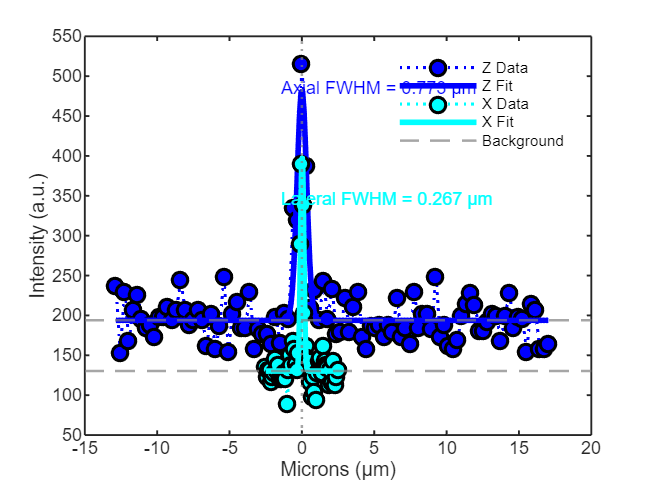

f3 = figure;
hold on

% Axial (Z) data and fit in blue
p1 = plot(xAxialShifted, yAxial, 'bo:', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k', ...
    'LineWidth', 1.2, 'DisplayName', 'Z Data');
p2 = plot(XfitAxShifted, YfitAx, 'b-', 'LineWidth', 2.2, 'DisplayName', 'Z Fit');
yline(optAx(4), '--', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);

% Lateral (X) data and fit in cyan (was magenta)
p3 = plot(xLatShifted, yLat, 'co:', 'MarkerFaceColor', 'c', 'MarkerEdgeColor', 'k', ...
    'LineWidth', 1.2, 'DisplayName', 'X Data');
p4 = plot(XfitLatShifted, YfitLat, 'c-', 'LineWidth', 2.2, 'DisplayName', 'X Fit');
p5 = yline(optLat(4), '--', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1, 'DisplayName', 'Background');

% Axis and legend
xline(0, ':', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);
xlabel('Microns (µm)');
ylabel('Intensity (a.u.)');
% xlim([-1.5, 1.5]);
set(gca, 'LineWidth', 0.75, 'FontSize', 7);
box on;
legend([p1, p2, p3, p4, p5], 'Location', 'northeast', 'Box', 'off', 'FontSize', 6);

% FWHM Annotations in top-left corner
text(-1.45, 0.94 * maxAxPeak, sprintf('Axial FWHM = %.3f µm', FWHM_ax), ...
    'FontSize', 7, 'FontName', 'Helvetica', 'Color', 'b');

text(-1.45, 0.87 * maxLatPeak, sprintf('Lateral FWHM = %.3f µm', FWHM_lat), ...
    'FontSize', 7, 'FontName', 'Helvetica', 'Color', 'c');

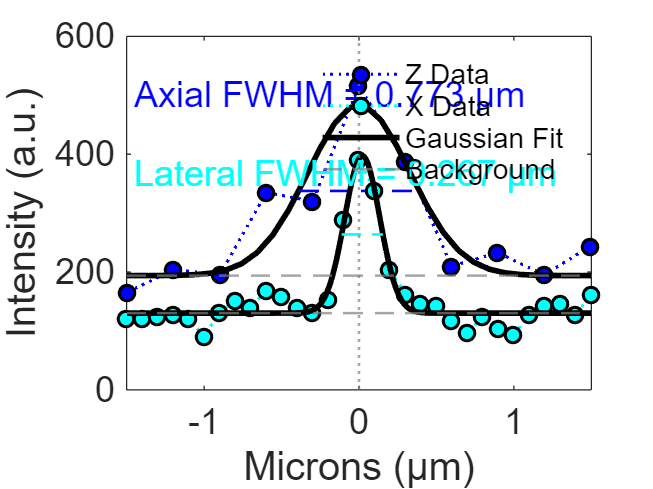

f3 = figure;
set(f3, 'Units', 'inches', 'Position', [1, 1, 8, 6]); % 8 inches wide, 6 tall
hold on

% --- Axial Plot (Blue) ---
p1 = plot(xAxialShifted, yAxial, 'bo:', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k', ...
    'LineWidth', 1.2, 'DisplayName', 'Z Data');
p2 = plot(XfitAxShifted, YfitAx, 'k-', 'LineWidth', 2.2, 'DisplayName', 'Gaussian Fit');
yline(optAx(4), '--', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);

% Axial FWHM lines
trueHalfMaxAx = min(YfitAx) + (max(YfitAx) - min(YfitAx)) / 2;
FWHM_X_Ax = optAx(2) + [-1, 1] * FWHM_ax / 2;
FWHM_X_Ax_shifted = FWHM_X_Ax - x0_ax;
plot(FWHM_X_Ax_shifted, [trueHalfMaxAx, trueHalfMaxAx], 'b--', 'LineWidth', 1);


% --- Lateral Plot (Cyan) ---
p3 = plot(xLatShifted, yLat, 'co:', 'MarkerFaceColor', 'c', 'MarkerEdgeColor', 'k', ...
    'LineWidth', 1.2, 'DisplayName', 'X Data');
plot(XfitLatShifted, YfitLat, 'k-', 'LineWidth', 2.2);
p5 = yline(optLat(4), '--', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1, 'DisplayName', 'Background');

% Lateral FWHM lines
trueHalfMaxLat = min(YfitLat) + (max(YfitLat) - min(YfitLat)) / 2;
FWHM_X_Lat = optLat(2) + [-1, 1] * FWHM_lat / 2;
FWHM_X_Lat_shifted = FWHM_X_Lat - x0_lat;
plot(FWHM_X_Lat_shifted, [trueHalfMaxLat, trueHalfMaxLat], 'c--', 'LineWidth', 1);


% --- Axis, Labels, Legend, Text ---
xline(0, ':', 'Color', [0.5, 0.5, 0.5], 'LineWidth', 1);
xlabel('Microns (µm)', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel('Intensity (a.u.)', 'FontSize', 12, 'FontName', 'Helvetica');
xlim([-1.5, 1.5]);

set(gca, 'LineWidth', 1, 'FontSize', 14, 'FontName', 'Helvetica');
box on;
legend([p1, p3, p2, p5], 'Location', 'northeast', 'Box', 'off', 'FontSize', 11);

% FWHM annotations (larger font, top left)
text(-1.45, 0.97 * maxAxPeak, sprintf('Axial FWHM = %.3f µm', FWHM_ax), ...
    'FontSize', 14, 'FontName', 'Helvetica', 'Color', 'b');
text(-1.45, 0.92 * maxLatPeak, sprintf('Lateral FWHM = %.3f µm', FWHM_lat), ...
    'FontSize', 14, 'FontName', 'Helvetica', 'Color', 'c');

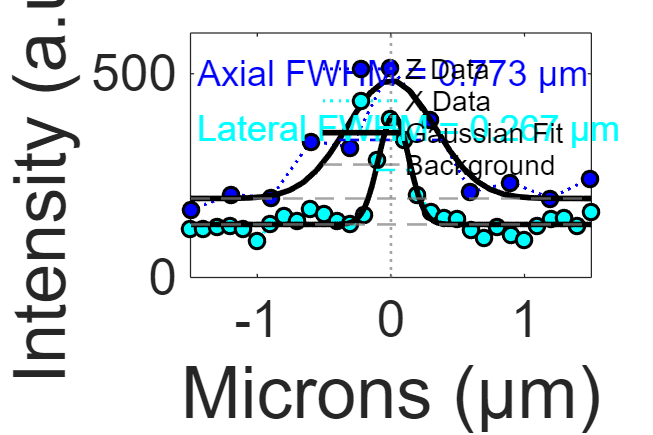


% Format
figWidth  = 9;    % inches (adjust as needed)
figHeight = 6;    % inches
set(gcf, ...
    'Units',      'inches', ...
    'Position',   [1 1 figWidth figHeight], ...
    'PaperUnits', 'inches', ...
    'PaperPosition', [0 0 figWidth figHeight] ...
);

% 2) Use Nature‑style fonts and large sizes:
set(gca, ...
    'FontName', 'Helvetica', ...
    'FontSize', 20, ...      % tick labels
    'LabelFontSizeMultiplier', 1.4 ...  % makes axis labels ~17 pt
);



saveas(gcf, fullfile(outputFolder, 'Ex_Fig.png'));
print(gcf, fullfile(outputFolder, 'Ex_Fig'), '-dpng', '-r600');
% For Adobe Illustrator
print(gcf, fullfile(outputFolder, 'Ex_Fig'), '-depsc', '-r600');